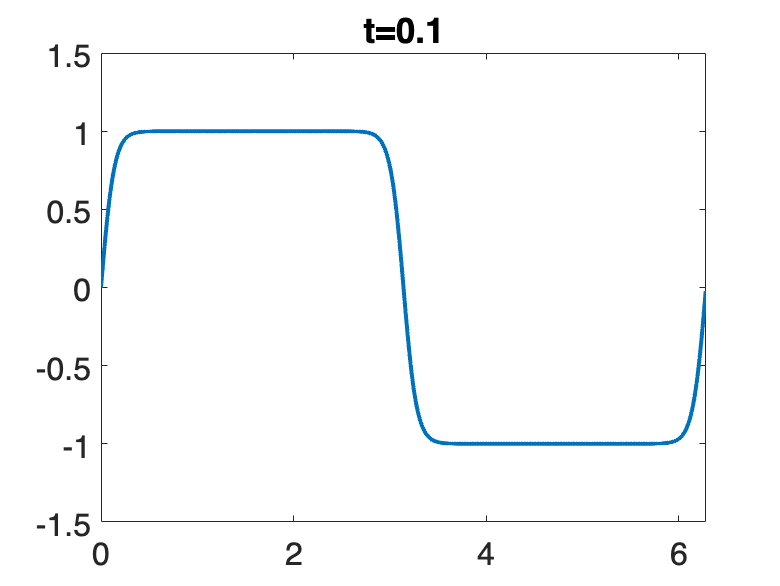

% Set up parameters
L = 2*pi;
Nx= 2^11;
h = L/Nx;
x = h*(0:Nx-1);
phi0=0.2*sin(x);
para.dt=1e-4;
para.T=1e-1;

% Call the Forward Euler solver
[phi,r,E]=CH1d_SAV_FE(para);

% Plot the result at t=0.1
plot(x,phi,"Linewidth",2);
xlim([0 2*pi]);ylim([-1.5 1.5]);
set(gca,'FontSize',16);title(['t=0.1']);

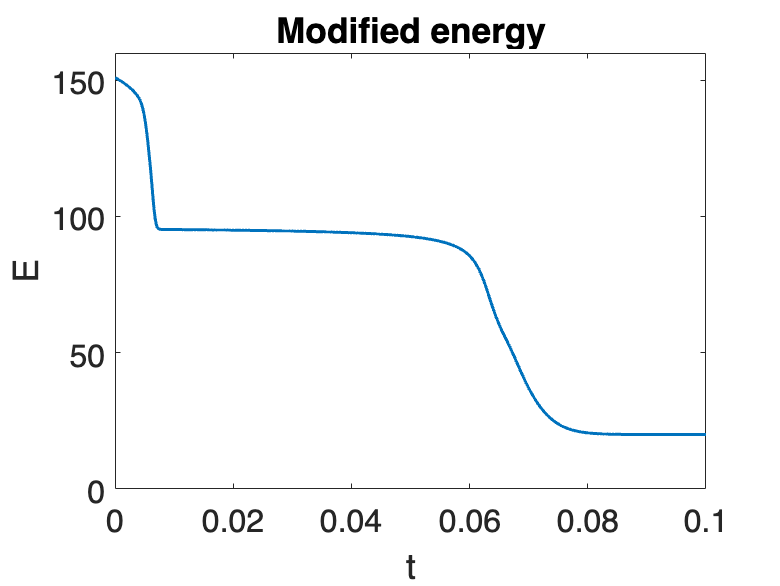


% Plot the modified energy
dt=para.dt;T=para.T;
plot((0:dt:T),E,'LineWidth',1.5);set(gca,'FontSize',16);
title('Modified energy')
xlabel('t');ylabel('E');

Functions

function [phi,r,E] = CH1d_SAV_FE(para)
% Solve 1D Cahn Hilliard equaiton
% \phi_t = \Delta \mu
% \mu = \Delta\phi + (\phi^3 - \phi)/epsilon^2

global dt epsilon k k2 k4 C0 h L

%% Parameters
T  = para.T;
dt = para.dt;
t  = 0;
Nt = round(T/dt);
E  = zeros(1,Nt+1);  

L = 2*pi;
Nx= 2^11;
h = L/Nx;

x = h*(0:Nx-1);
k = 1i*[0:Nx/2 -Nx/2+1:-1]*(2*pi/L);
k2 = k.^2;
k4 = k2.^2;

epsilon = 0.1;
C0 = 0;

phi0 = 0.2*sin(x);
r0 = r0_fun(phi0);

% Initial modified energy
E(1)=h*sum(1/2*phi0.*(-Lap(phi0)))+r0^2;

%% Time iteration
for nt = 1:Nt

    t = t+dt;
    
    % Step 1
    b = b_fun(phi0);
    
    g = g_fun(phi0,r0,b);  
    
    AiLb = A_inv(Lap(b));
    Aig  = A_inv(g);    
    
    gamma = -fft(b.*AiLb);
    gamma = gamma(1)*h;
    
    % Step 2      
    bphi = fft(b.*Aig);
    bphi = bphi(1)*h/(1+dt/2*gamma);
    
    % Step 3
    phi = dt/2*bphi.*AiLb + Aig;  
    r   = r_fun(phi,phi0,r0,b);   
    
%% update phi0, r0
    phi0 = phi;     
    r0   = r;  

%% Modified energy
    E(1+nt)=h*sum(1/2*phi.*(-Lap(phi)))+r^2;
end

end
function r0 = r0_fun(phi0)
global C0 h
    r0 = sqrt(h*sum(f(phi0)) + C0);
end

function r = r_fun(phi,phi0,r0,b)
global h 
    bphi0 = fft(b.*phi0);
    bphi0 = h*bphi0(1);
    bphi  = fft(b.*phi);
    bphi  = h*bphi(1);
 
    r = r0 + 1/2*(bphi-bphi0);

    E1 = fft(f(phi0));
end

function b = b_fun(phi)
global C0 h
    E1 = fft(f(phi));
    b = df(phi)./sqrt(E1(1)*h+C0);
end

function g = g_fun(phi0,r0,b)
global dt h
    bphi0 = fft(b.*phi0);
    bphi0 = h*bphi0(1);
    g = phi0 + dt.*Lap(b)*(r0-1/2*bphi0);

    E1 = fft(f(phi0));
end

function Lphi=Lap(phi)
global k2
    Lphi=real(ifft((k2.*fft(phi))));
end

function Dphi = Diff(phi)
global k
    Dphi=real(ifft((k.*fft(phi))));
end

function Ai = A_inv(phi)
global dt k4
    Ai = real(ifft(fft(phi)./(1+dt*k4)));
end

function fphi = f(phi)
global epsilon
    fphi = (phi.^2-1).^2/(4*epsilon^2);
end

function dfphi = df(phi)
global epsilon
    dfphi = (phi.^3 - phi)/epsilon^2;
end